# **Hava Kalitesi ve Kirlilik Analizi**

## 1. Veriyi içe aktarma

data = readtable('AirQuality.csv', 'PreserveVariableNames', true, 'Delimiter', ';', 'DecimalSeparator', ',');
data = data(:,1:15); % gereksiz son sütunları temizle.

## 2. Eksik verileri doldurma - Interpolation

data_raw = data; % temizlenmemiş veriyi sakla.
rawDate = string(data.Date);
rawTime = string(data.Time);
DateTimeStr = rawDate + " " + rawTime;

TimeAxis = datetime(DateTimeStr, 'InputFormat', 'dd/MM/yyyy HH.mm.ss', 'Locale', 'en_US'); % tarih ve saat sütunlarını birleştirme.
[TimeAxis, sortIdx] = sort(TimeAxis);
data = data(sortIdx, :);
data_raw = data_raw(sortIdx, :);

numericVars = data.Properties.VariableNames(3:end); % tarih ve saat hariç sütunları al.
data_clean = fillmissing(data, 'linear', 'DataVariables', numericVars); % lineer interpolasyon ile eksikleri doldurma.

## 3. Görselleştirme

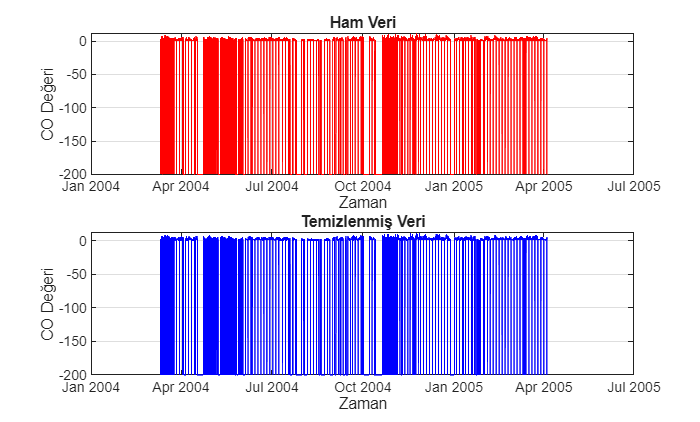

% örnek CO verisini görselleştirelim.
figure;
subplot(2,1,1);
plot(TimeAxis, data_raw.("CO(GT)"), 'r');
title('Ham Veri')
xlabel('Zaman');
ylabel('CO Değeri');
grid on;

subplot(2,1,2);
plot(TimeAxis, data_clean.("CO(GT)"), 'b-');
title('Temizlenmiş Veri');
xlabel('Zaman');
ylabel('CO Değeri');
grid on;

## 4. Özdeğer - Özvektör Analizi (PCA)

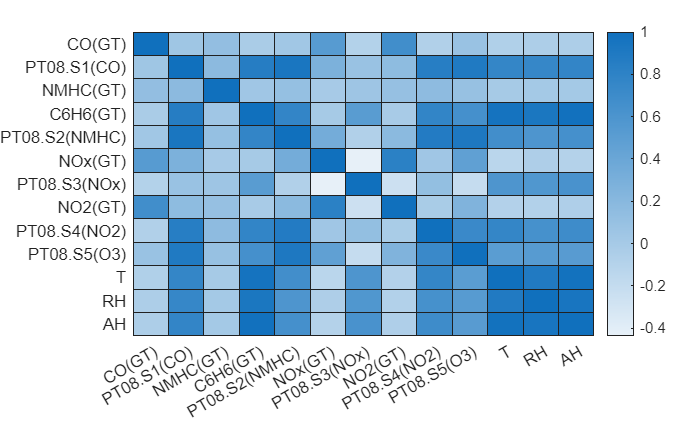

% veriyi matrise çevir
X_raw = table2array(data_clean(:, 3:end));
varNames = data_clean.Properties.VariableNames(3:end); % tarih-saat sütununu at.

% normalizasyon, ölçeklendirme, Z-score
X_norm = zscore(X_raw);

% kovaryans matrisi hesabı
covMatrix = cov(X_norm);

figure;
h = heatmap(numericVars, numericVars, covMatrix);


% özdeğer - özvektör hesabı
[V, D] = eig(covMatrix);

% sıralamayı büyükten küçüğe çevirme.
[eigenvalues, idx] = sort(diag(D), 'descend');
eigenvectors = V(:, idx);

% varyans açıklama oranları
total_var = sum(eigenvalues);
explained_var = (eigenvalues/total_var)*100;
cumulative_var = cumsum(explained_var);

disp('--- PCA Sonuçları---');

--- PCA Sonuçları---


fprintf('1. Temel bileşen (PC1) varyansın %% %.2f kısmını açıklıyor.', explained_var(1));

1. Temel bileşen (PC1) varyansın % 50.65 kısmını açıklıyor.

fprintf('İlk 2 bileşen toplam varyansın %% %.2f kısmını açıklıyor.', cumulative_var(2));

İlk 2 bileşen toplam varyansın % 73.30 kısmını açıklıyor.

## 5. Görselleştirme

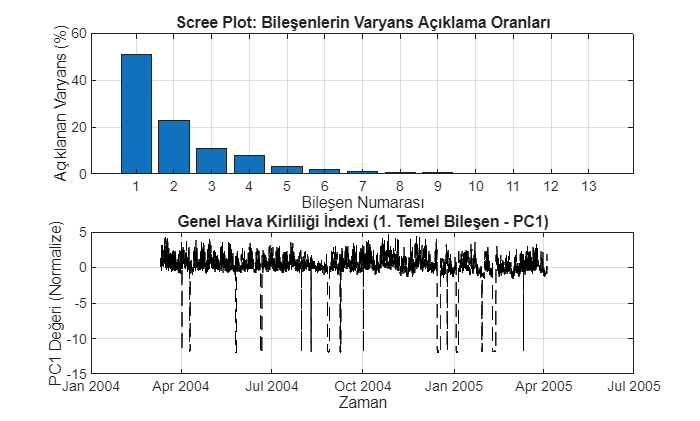

% Scree Plot - Yamaç Grafiği
figure;
subplot(2,1,1);
bar(explained_var);
title('Scree Plot: Bileşenlerin Varyans Açıklama Oranları');
xlabel('Bileşen Numarası');
ylabel('Açıklanan Varyans (%)');
grid on;

% verinin tek boyuta indirgenmiş hali (PC1 Zaman Serisi)
PC1 = X_norm * eigenvectors(:, 1);

subplot(2,1,2);
plot(TimeAxis, PC1, 'k--');
title('Genel Hava Kirliliği İndexi (1. Temel Bileşen - PC1)');
xlabel('Zaman');
ylabel('PC1 Değeri (Normalize)');
grid on;


% değişkenleri kaydet.
save('pca_results.mat', 'PC1', 'TimeAxis', 'eigenvalues', 'explained_var');

## 6. Eğri Uydurma

load('pca_results.mat'); % kaydedilen sonuçları yükle.

% zaman eksenini sayısallaştırma
t_numeric = hours(TimeAxis-TimeAxis(1));

% eğri uydurma - en küçük kareler yöntemi
pol_deg = 10;
[p, S, mu] = polyfit(t_numeric, PC1, pol_deg);


## 7. Doğrusal Olmayan Denklem Çözümü: Kritik Eşik Analizi

esik_deger = 2.0;
p_esik = p;
p_esik(end) = p_esik(end) - esik_deger;

kokler = roots(p_esik);
kokler_gercek = kokler * mu(2) + mu(1);
zaman_noktalari = kokler(imag(kokler_gercek)==0 & kokler_gercek>=0 & kokler_gercek<=max(t_numeric));
zaman_noktalari = sort(zaman_noktalari);

fprintf('Kirlilik indexi %0.1f değerini şu saatlerde kesmektedir:\n', esik_deger);

Kirlilik indexi 2.0 değerini şu saatlerde kesmektedir:


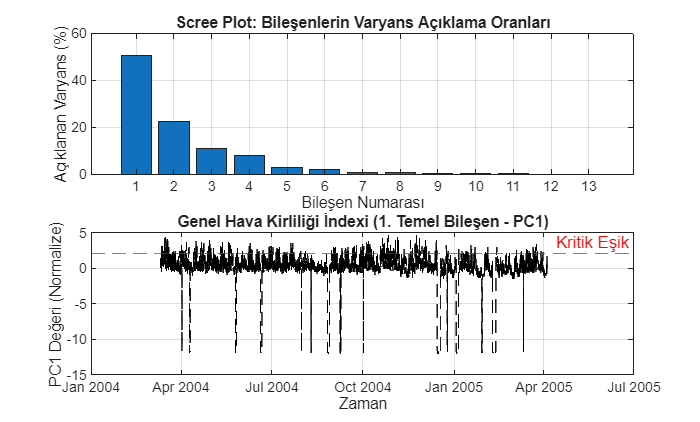

disp(zaman_noktalari);

hold on;
yline(esik_deger, '--r', 'Kritik Eşik');
plot(zaman_noktalari, repmat(esik_deger, size(zaman_noktalari)), 'ko', 'MarkerFaceColor', 'y');
hold off;

## 8. Sayısal İntegral

% pürüzsüz veriyi üretelim.
y_fit = polyval(p, t_numeric, S, mu);

% sayısal integral alma.
toplam_kirlilik = trapz(t_numeric, abs(y_fit));

fprintf("\n--- Modelleme Sonuçları ---\n");


--- Modelleme Sonuçları ---


fprintf('Uydurulan Polinom Derecesi: %d\n', pol_deg);

Uydurulan Polinom Derecesi: 10


fprintf('Hesaplanan Toplam Kirlilik Yükü (İntegral Alanı): %.2f birim\n', toplam_kirlilik);

Hesaplanan Toplam Kirlilik Yükü (İntegral Alanı): 4350.69 birim


## 9. Son Grafik

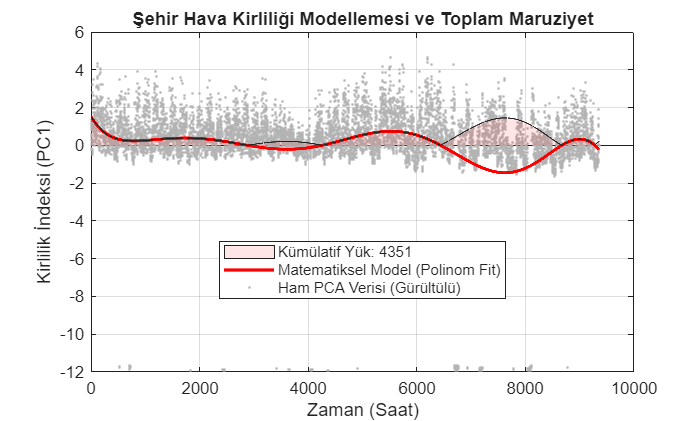

figure('Name', 'Final Model', 'Color', 'w');

% gerçek PC1 verisi
plot(t_numeric, PC1, '.', 'Color', [0.7 0.7 0.7], 'MarkerSize', 4, 'DisplayName', 'Ham PCA Verisi (Gürültülü)');
hold on;

% uydurduğumuz matematiksel model
plot(t_numeric, y_fit, 'r-', 'LineWidth', 2, 'DisplayName', 'Matematiksel Model (Polinom Fit)');

% integral alanı
area(t_numeric, abs(y_fit), 'FaceAlpha', 0.1, 'FaceColor', 'r', 'DisplayName', ['Kümülatif Yük: ' num2str(toplam_kirlilik, '%.0f')]);

title('Şehir Hava Kirliliği Modellemesi ve Toplam Maruziyet');
xlabel('Zaman (Saat)');
ylabel('Kirlilik İndeksi (PC1)');
legend('Location', 'best');
grid on;